# TD-OCT example

% Jonghwan Lee, Apr 2021

The Michelson interferometer signal from `Michelson interferometer example.mlx`, but with $L$ as a variable and $z$ as constant.  All lengths are in [m].

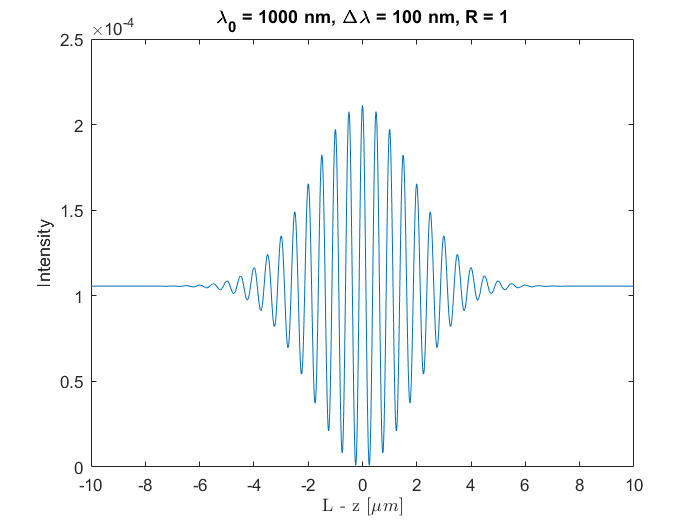

clear

c = 3e8;
eps0 = 8.85e-12;

n = 1;
E0 = 1.0;
z = 50e-3;  % z is constant
lam0 = 1000e-9;
fwhmLam = 100e-9;
R = 1;

dL = 0.01e-6;
L = z + (-10e-6:dL:10e-6);  % move the mirror to scan the depths around the sample

k0 = 2*pi/lam0;  
w0 = c * k0;
kp0 = 1/c;
fwhmOmega = fwhmLam/lam0 * w0;  % approximately
sigmaOmega = fwhmOmega / (2*sqrt(2*log(2)));
    
I1 = 1 + abs(R)^2 + 2 * abs(R) * ... 
    exp( -2 * sigmaOmega^2 * kp0^2 * (z-L).^2 ) ...
    .* cos( 2 * k0 * (z-L) + angle(R) );

I = 1/16/pi*n*c*eps0*E0^2 * I1;

figure
plot((L-z)*1e6,I)
xlim([-10 10])
xlabel('L - z [$\mu m$]','Interpreter',"latex")
ylabel('Intensity')
title(['\lambda_0 = ' num2str(lam0*1e9) ' nm, \Delta\lambda = ' num2str(fwhmLam*1e9) ' nm, R = ' num2str(R)])    

Extract the enveolop as an OCT signal

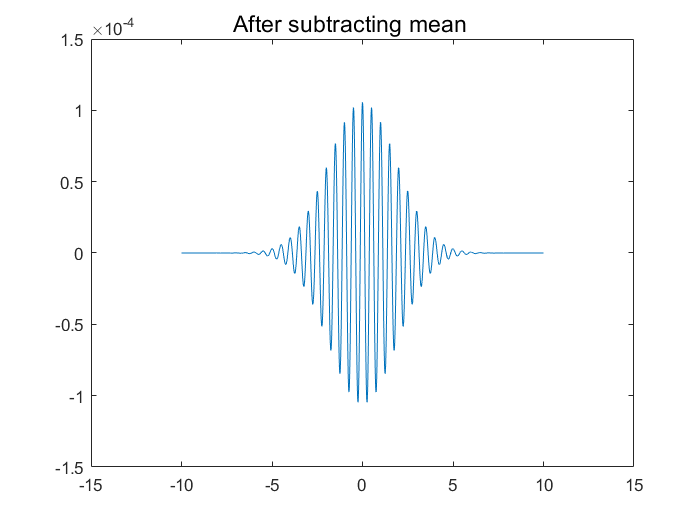

Ioct = I;  % to be updated as OCT signal

Ioct = Ioct - mean(Ioct);  % subtract mean

figure
plot((L-z)*1e6,Ioct)
sgtitle('After subtracting mean')

Absolute

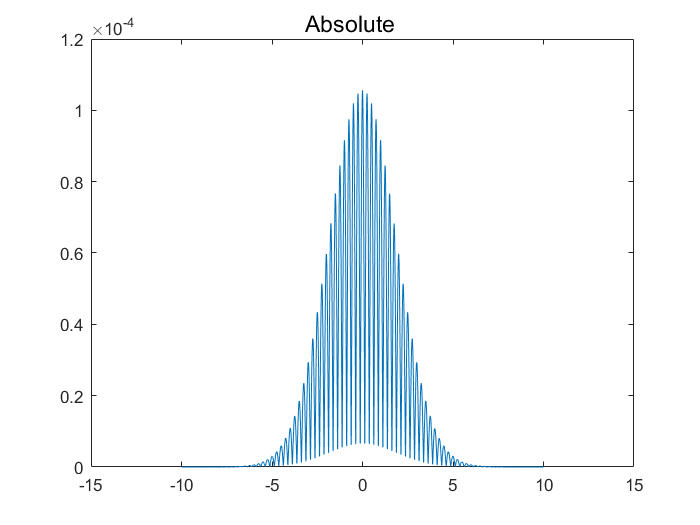

Ioct = abs(Ioct);

figure
plot((L-z)*1e6,Ioct)
sgtitle('Absolute')

Low-pass filtering

Increase the kernel size until the result looks indeed low-pass filtered.

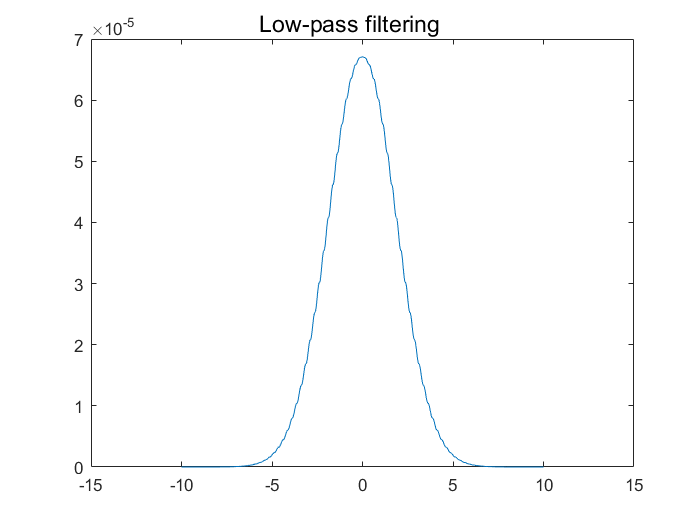

Ioct = conv(Ioct,ones(50,1)/50,'same');

figure
plot((L-z)*1e6,Ioct)
sgtitle('Low-pass filtering')

Measure FWHM.  *You can measure this manually.*

IoctMax = max(Ioct);
Isign = sign(Ioct-IoctMax/2);  % sign will change at the intersection with half max
IsignDiff = abs(diff(Isign));  % diff will be 2 at the point the sign changes (i.e., intersection)
iz = find(IsignDiff == 2);  % ideally 2 points
if numel(iz) == 2
    fwhm = abs(diff(iz))*dL;
else
    error('The intersection points ~= 2')
end

fwhm*1e6

ans = 4.4600

Coherence length

cohLength = 0.9 * lam0^2 / fwhmLam * 1e6  % [um]

cohLength = 9